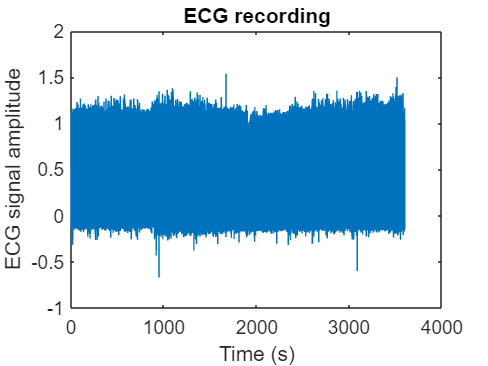

% Load the ECG data
load('Placeholder.mat');

% Set the sampling frequency and the time vector
fs = 1000;  % Hz
t = (0:length(data)-1) / fs;

% Find the R peaks in the ECG signal
[peaks,locs] = findpeaks(data, t, 'MinPeakHeight', 0.3, 'MinPeakDistance', 0.3);
% Minpeakheight is not allways necessary

% Calculate the RR intervals
rr_intervals = diff(locs);

% Plot the ECG signal
figure;
plot(t, data);
xlabel('Time (s)');
ylabel('ECG signal amplitude');
title('ECG recording');

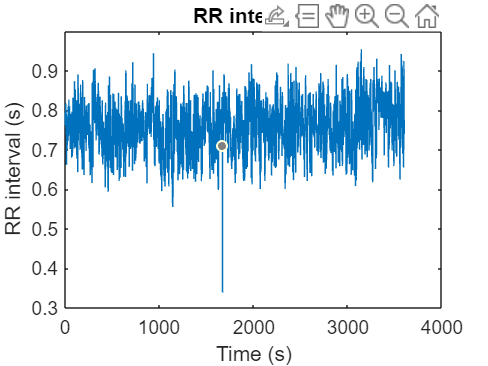


% Plot the RR intervals
figure;
plot(locs(2:end), rr_intervals);
xlabel('Time (s)');
ylabel('RR interval (s)');
title('RR intervals');

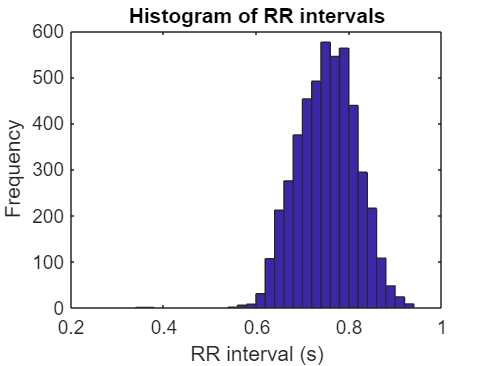



% Create a histogram of the RR intervals with customizable bin widths and edges
bin_width = 0.02;  % Change this to set the width of each bin
bin_edges = min(rr_intervals):bin_width:max(rr_intervals);  % Change this to set the edges of the bins
n = histcounts(rr_intervals, bin_edges);



% Plot the histogram
figure;
bar(bin_edges(1:end-1), n, 'histc');
xlabel('RR interval (s)');
ylabel('Frequency');
title('Histogram of RR intervals');

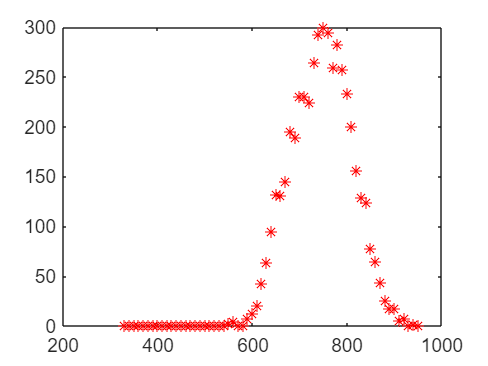


%show the ms diff on x axis
[N,EDGES] = histcounts(rr_intervals*1000);


% plot the edges point with stars
figure; plot(EDGES(1:end-1),N,'r*')

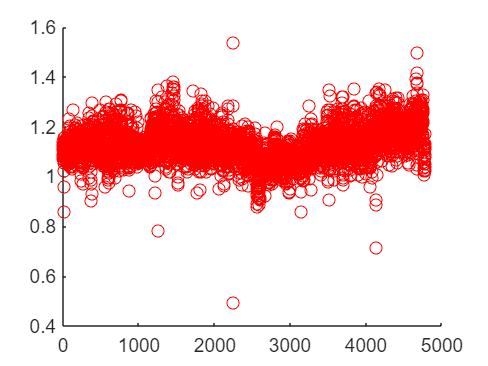


figure; hold on;
plot(peaks, 'ro');